clear all;
load fisheriris.mat


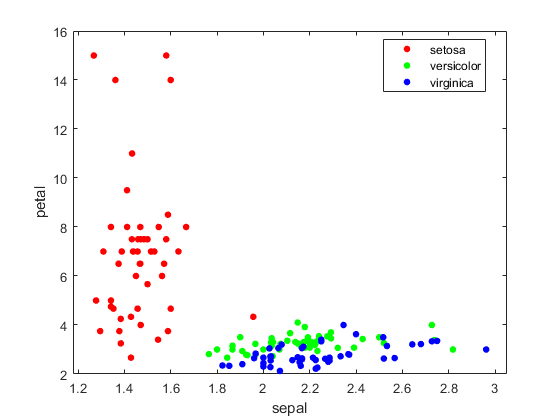

meas;
species;
% Extract and separate Sepal and Petal values
sepal = meas(: , 1) ./ meas(: , 2);
petal = meas(: , 3) ./ meas(: , 4);
% Plot value-relations
gscatter(sepal, petal, species);

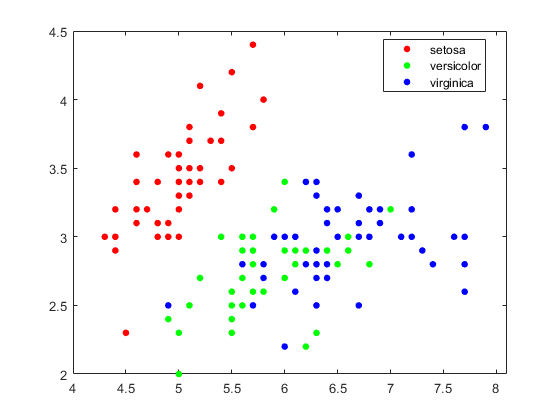

gscatter(meas(:, 1), meas(: , 2) , species);

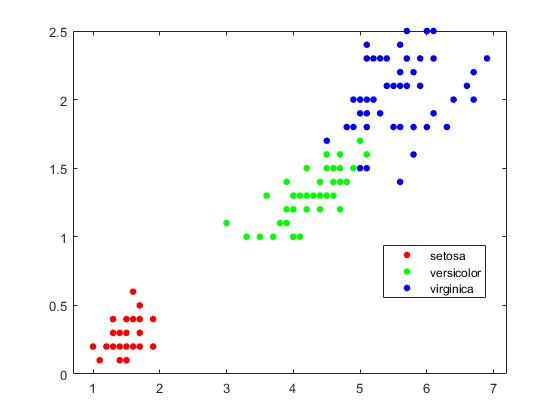

gscatter(meas(:, 3), meas(: , 4) , species);

% Divide dataset into training and testing data and assign new variables 
% based on that partition
cv = cvpartition(species, "HoldOut", 0.2)

cv = Hold-out cross validation partition
   NumObservations: 150
       NumTestSets: 1
         TrainSize: 120
          TestSize: 30

trainMeasure = meas(cv.training, :);
trainSpecies = species(cv.training, :);
testMeasure = meas(cv.test, :);
testSpecies = species(cv.test, :);

% Create and train machine learning model based on trainingdata
Model = fitcknn(trainMeasure, trainSpecies, "NumNeighbors", 5, "Standardize", 1)

Model =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'setosa'  'versicolor'  'virginica'}
           ScoreTransform: 'none'
          NumObservations: 120
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


% Use model to predict the labels of the dataset "testMeasure"
pred = predict(Model, testMeasure);
% Turn predictions into a string in order to compare
predString = string(pred);
% Extract the amount of correct predictions. Accuracy determines how good
% the model is at predicting
correct = predString == testSpecies;
accuracy = sum(correct)/numel(pred);

% Extract the amount of incorrect predictions. Missclassrate determines how
% bad the model is at predicting
wrong = predString ~= testSpecies;
misclassrate = sum(wrong)/numel(pred)

misclassrate = 0

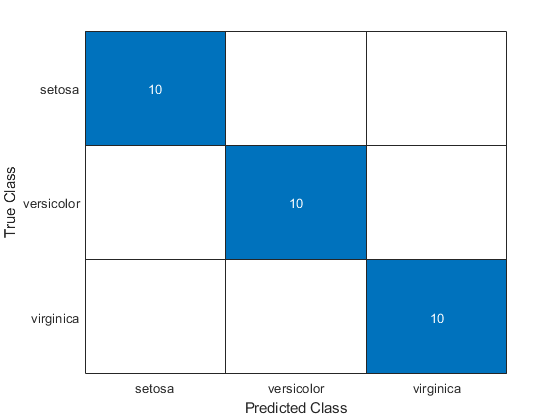

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: {3×1 cell}

  Show all properties



% Display clissifications
confusionchart(testSpecies, pred)